PC 56 是型号

T0-28, 0, 22H-71-11101, 推土铲总成, 1, DJB00001-, 工作装置-推土铲-推土铲总成, 

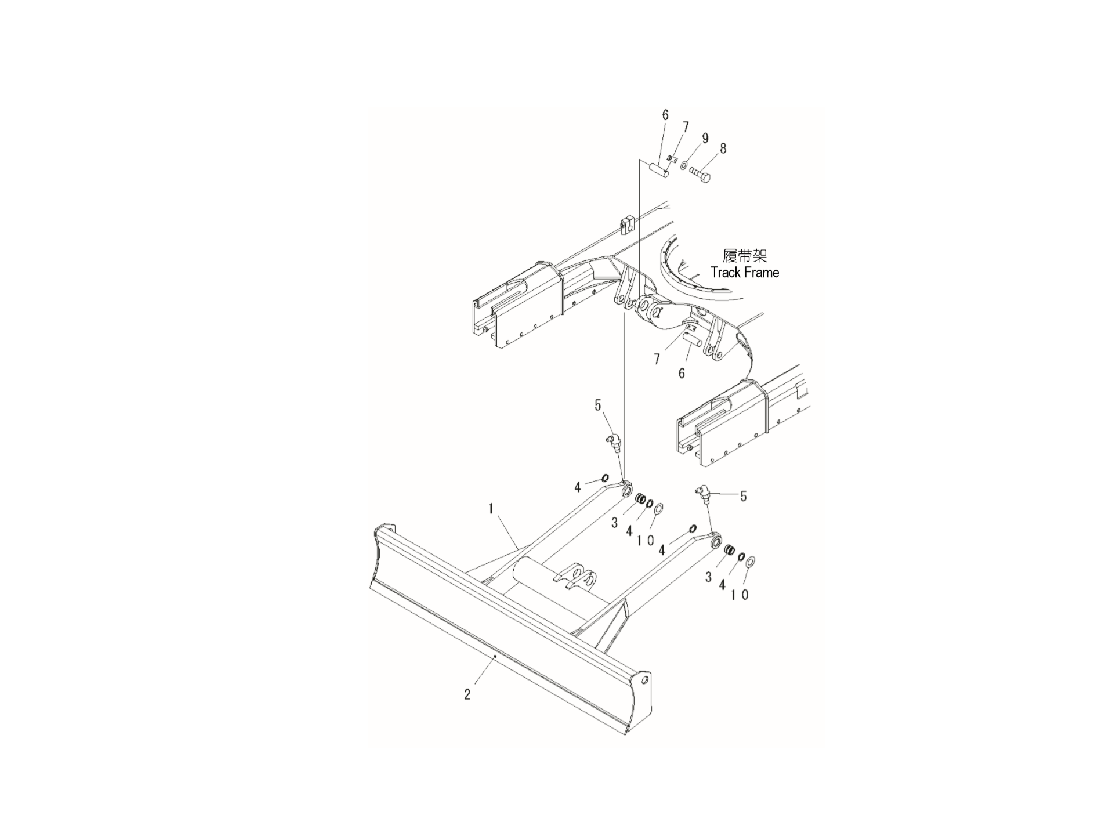

cd(rootDirectory)
search_user1

% handles 的数据结构：
% keywords           用户输入的关键字
% userChoice         1x3 double，用户的选择（三个 popup_menu 的下标），默认为 0
% rootDirectory      根目录
% modelMatrix        厂家-型号的矩阵
%                    三列为 1厂家 2型号 3厂家型号
% modelRanking       ，厂家-型号的匹配度排名
% indexMatrix        用户选择型号的目录
%                    五列为  1器件编号  2器件名  3部件名  4图片编号  5页码
% Map_page_name      用户选择型号的页码-名称映射
% Map_page_fig       用户选择型号的页码-图片映射
% informationMatrix  用户选择型号的零件信息
%                    七列为 1页码 2图中序号 3件号 4名称 5数量 6系列号 7主串
% informationRank    {score index}，用户选择型号的零件匹配度排名

function search_user1(varargin)
    handles.userChoice = [0 0 0];
    
    if (isempty(varargin))
        handles.keywords = 'PC56推土机总成';
    else
        handles.keywords = varargin{1};
    end
    
    handles.rootDirectory = pwd;

    UpdateModelMatrix(handles,'.');
end


% 列出给定目录下的文件，返回 string 数组（列向量）
% 如果 onlydir 为 true，只返回文件夹
function fileArray = ListDirectory(path, onlydir)
    listing = dir(path);
    fileArray = strings(size(listing));
    fileArray(:) =  {listing.name};
    if (onlydir)
        fileArray = fileArray([listing.isdir]);
    end
    % 删除 . 开头的文件/文件夹
    fileArray(startsWith(fileArray(:),'.')) = [];
end

% 输入主串数组和关键字串，输出分数（降序排列）及其下标
function [score, index] = MatchString(strArray, pattern)
    cpattern = char(pattern);
    scoreMax = 50;
    score = zeros(1,scoreMax);
    index = zeros(1,scoreMax);
    f = @(l,k) l.^2 * (2 - 2.^(1-k));    
    for t = 1:length(strArray)
        score1 = 0;
        for i = 1:strlength(cpattern)
            for j = i:strlength(cpattern)
                k = length(strfind(strArray(t),cpattern(i:j)));
                l = j - i + 1;
                score1 = score1 + f(l,k);
            end
        end
        if (score1 > score(scoreMax))
            score(scoreMax) = score1;
            index(scoreMax) = t;
            [score, idx] = sort(score,'descend');
            index = index(idx);
        end
    end
end

% modelMatrix 两列为 1厂家 2型号 3厂家型号
function UpdateModelMatrix(handles, path)
    manufacturerString = ListDirectory(path, true);
    handles.modelMatrix = [];
    for manufacturerString1 = manufacturerString'
        modelString = ListDirectory(char(path + "\" + manufacturerString1), true);
        manufacturerString111 = strings(size(modelString));
        manufacturerString111(:) = manufacturerString1;
        manufacturerModelString = manufacturerString111 +  modelString;
        handles.modelMatrix = [handles.modelMatrix; 
            manufacturerString111, modelString, manufacturerModelString];
    end
    
    % 更新排名矩阵
    [score, index] = MatchString(handles.modelMatrix(:,3), handles.keywords);
    handles.modelRanking.score = score;
    handles.modelRanking.index = index;
    
    handles.userChoice(1) = 1;
    UpdateModelDirectory(handles);
end

function UpdateModelDirectory(handles)
    modelIndex = handles.modelRanking.index(handles.userChoice(1));
    GetModelDirectory = @(x) handles.rootDirectory + "\" + x(1) + "\" + x(2);
    handles.modelDirectory = GetModelDirectory(handles.modelMatrix(modelIndex,:));
    handles = UpdateIndexMatrix(handles);
    UpdateInformationMatrix(handles);
end

% indexMatrix 五列为  1器件编号  2器件名  3部件名  4图片编号  5页码
function handles = UpdateIndexMatrix(handles)
    indexFile = handles.modelDirectory + "\index.xlsx";
    handles.indexMatrix = readmatrix(indexFile,"OutputType",'string','NumHeaderLines',1);
    handles.indexMatrix = handles.indexMatrix(:, [1 2 4 6 7]);
    
    % 更新页码到器件名/图片编号的映射
    name = handles.indexMatrix(:,2) + "-" + handles.indexMatrix(:,3);
    handles.Map_page_name = containers.Map(handles.indexMatrix(:,5), name);
    handles.Map_page_fig = containers.Map(handles.indexMatrix(:,5), handles.indexMatrix(:,4));
end

% information 七列分别为 1页码 2图中序号 3件号 4名称 5数量 6系列号 7主串
function UpdateInformationMatrix(handles)
    informationFile = handles.modelDirectory + "\table.xlsx";
    informationMatrix = readmatrix(informationFile,"OutputType",'string','NumHeaderLines',1);
    informationMatrix(:,7) = string;
    for i = 1 : size(informationMatrix)
        informationMatrix(i,7) = handles.Map_page_name(char(informationMatrix(i,1))) + "-" ...
            + informationMatrix(i,4);
    end

    handles.informationMatrix = informationMatrix;
    
    [score, index] = MatchString(informationMatrix(:,7),handles.keywords);
    handles.informationRank.score = score;
    handles.informationRank.index = index;
     
    handles.userChoice(1) = 1;
    printInformation(handles);
end

function printInformation(handles)
    % 这里只实现显示第一个的信息
    
    index = handles.informationRank.index(1);
    fprintf('%s, ', handles.informationMatrix(index,:));
    
    fig_name = handles.Map_page_fig(handles.informationMatrix(index,1));
    fig = imread(handles.modelDirectory + "\graph\" + fig_name + ".png");
    image(fig);
    axis equal off;
end